# Neural Network for Identification of Musical Instruments

rng(123)
specDS = imageDatastore('Spectrograms',"IncludeSubfolders",true,"LabelSource","foldernames",'ReadFcn',@(f) imresize(imread(f),[100 100]));
[trainds, testds, validds] = splitEachLabel(specDS, 0.8,0.1,0.1,'randomized')

trainds =   ImageDatastore with properties:

                       Files: {
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img321.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img322.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img323.jpg'
                               ... and 955 more
                              }
                      Labels: [Bells; Bells; Bells ... and 955 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @(f)imresize(imread(f),[100,100])


testds =   ImageDatastore with properties:

                       Files: {
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img332.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img336.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img343.jpg'
                               ... and 118 more
                              }
                      Labels: [Bells; Bells; Bells ... and 118 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @(f)imresize(imread(f),[100,100])


validds =   ImageDatastore with properties:

                       Files: {
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img327.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img342.jpg';
                              'D:\DEEP_LEARNING_FILES\DATA_PROJECTS\Spectrograms\Bells\img358.jpg'
                               ... and 116 more
                              }
                      Labels: [Bells; Bells; Bells ... and 116 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @(f)imresize(imread(f),[100,100])


## Setting up the Network

numclass = 14;  %% There are 14 instruments that are to be identified.
dropoutProb = 0.02;

inputlayer = imageInputLayer([100 100 3])

inputlayer =   ImageInputLayer with properties:

                Name: ''
           InputSize: [100 100 3]

   Hyperparameters
    DataAugmentation: 'none'
       Normalization: 'zerocenter'
        AverageImage: []


 midLayers = [
     convolution2dLayer(3,16, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     maxPooling2dLayer(2,'Stride',2)
     
     convolution2dLayer(3,32, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     maxPooling2dLayer(2,'Stride',2,'Padding',[0 1])
     
     dropoutLayer(dropoutProb)
     convolution2dLayer(3,64, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     dropoutLayer(dropoutProb)
     convolution2dLayer(3,64, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     maxPooling2dLayer(2,'Stride',2,"Padding",[0 1])
     
     dropoutLayer(dropoutProb)
     convolution2dLayer(3,64, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     dropoutLayer(dropoutProb)
     convolution2dLayer(3,64, "Padding",'same')
     batchNormalizationLayer()
     reluLayer()
     
     maxPooling2dLayer([1 13])    
     ]

midLayers =   26x1 Layer array with layers:

     1   ''   Convolution           16 3x3 convolutions with stride [1  1] and padding 'same'
     2   ''   Batch Normalization   Batch normalization
     3   ''   ReLU                  ReLU
     4   ''   Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution           32 3x3 convolutions with stride [1  1] and padding 'same'
     6   ''   Batch Normalization   Batch normalization
     7   ''   ReLU                  ReLU
     8   ''   Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  1  1]
     9   ''   Dropout               2% dropout
    10   ''   Convolution           64 3x3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization   Batch normalization
    12   ''   ReLU                  ReLU
    13   ''   Dropout               2% dropout
    14   ''   Convo

OutLayers = [ 
    fullyConnectedLayer(numclass)
    softmaxLayer()
    classificationLayer()
    ]

OutLayers =   3x1 Layer array with layers:

     1   ''   Fully Connected         14 fully connected layer
     2   ''   Softmax                 softmax
     3   ''   Classification Output   crossentropyex

NetLayers = [
    inputlayer
    midLayers
    OutLayers
    ]

NetLayers =   30x1 Layer array with layers:

     1   ''   Image Input             100x100x3 images with 'zerocenter' normalization
     2   ''   Convolution             16 3x3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution             32 3x3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  1  1]
    10   ''   Dropout                 2% dropout
    11   ''   Convolution             64 3x3 convolutions with stride [1  1] and padding 'same'
    12   ''   Batch Normalization     Batch normalizatio

## Training the Network

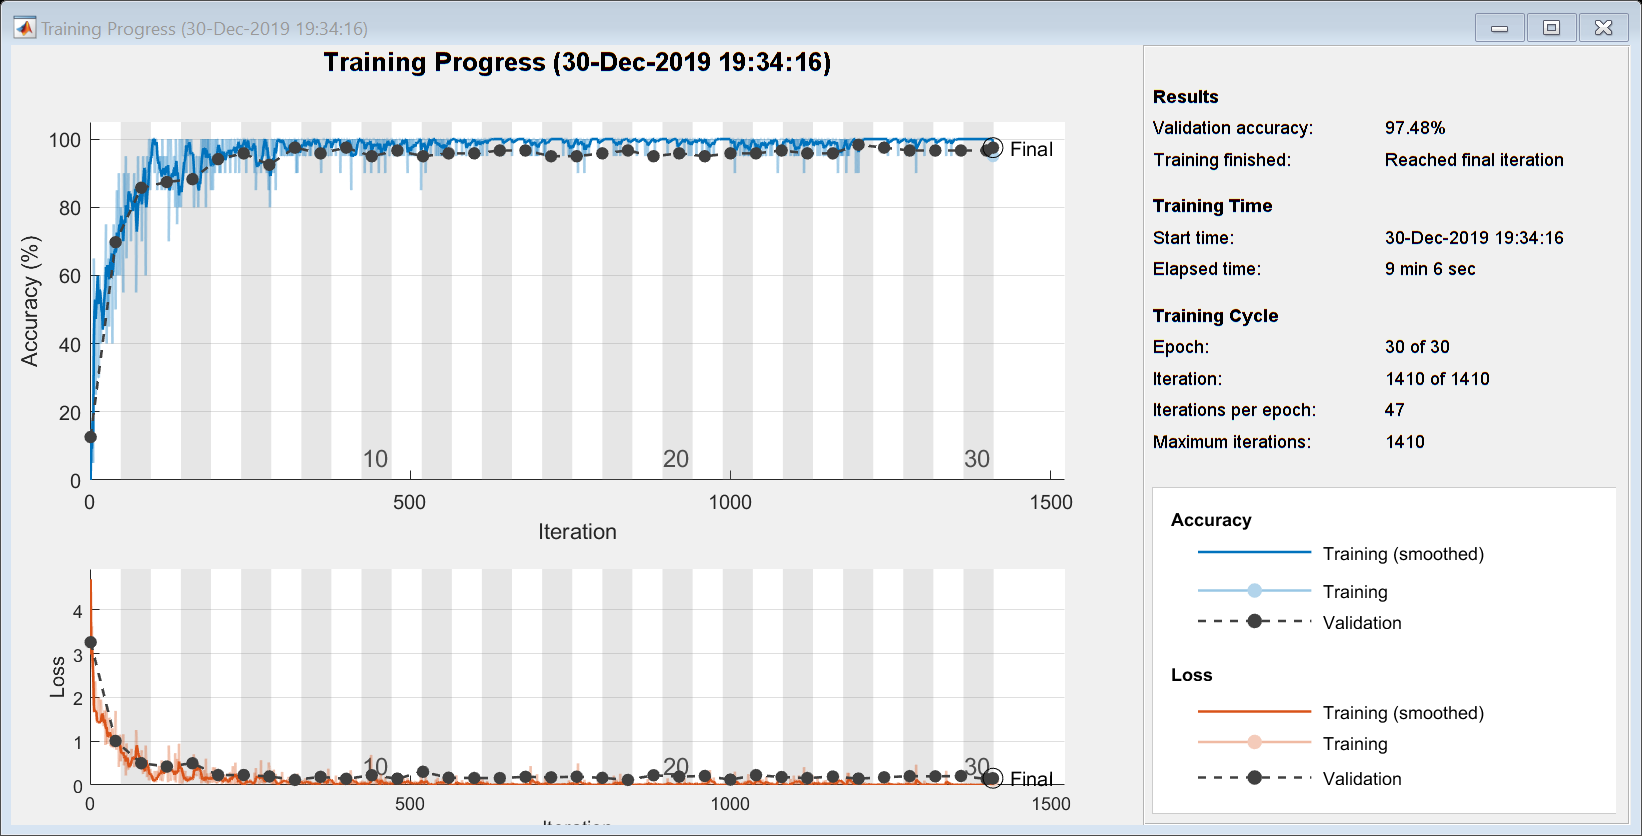

Training on single GPU.


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        0.00% |       12.61% |       4.6942 |       3.2591 |          0.0010 |
|       1 |          40 |       00:00:16 |       50.00% |       69.75% |       1.6913 |       1.0045 |          0.0010 |
|       2 |          50 |       00:00:20 |       75.00% |              |       0.8733 |              |          0.0010 |
|       2 |          80 |       00:00:31 |       85.00% |       85.71% |       0.7474 |       0.4967 |          0.

specNetwork =   SeriesNetwork with properties:

    Layers: [30×1 nnet.cnn.layer.Layer]


options = trainingOptions("adam","InitialLearnRate",0.001,"Plots","training-progress",...
    "MiniBatchSize",20,"Shuffle","every-epoch","ValidationData",validds,"ValidationFrequency",40,...
    "LearnRateDropFactor",0.97,"GradientThreshold",1,"LearnRateSchedule","piecewise");
specNetwork = trainNetwork(trainds,NetLayers,options)

## Evaluating the Network

testpred=classify(specNetwork,testds)

testpred = 121×1 categorical array
     Bells 
     Bells 
     Vibraphone 
     Bells 
     Bells 
     Bells 
     Bells 
     Bells 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Violin 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Clarinet 
     Crotales 
     Crotales 
     Crotales 
     Crotales 
     Crotales 
     Crotales 
     Crotales 
     Crotales 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Double Bass 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Flute 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Piano 
     Saxophone 
     Saxophone 
     Saxophone 
     Clarinet 
     Sax

a=nnz(testpred==testds.Labels)

a = 118

b=length(testpred)

b = 121

acc=a/b

acc = 0.9752

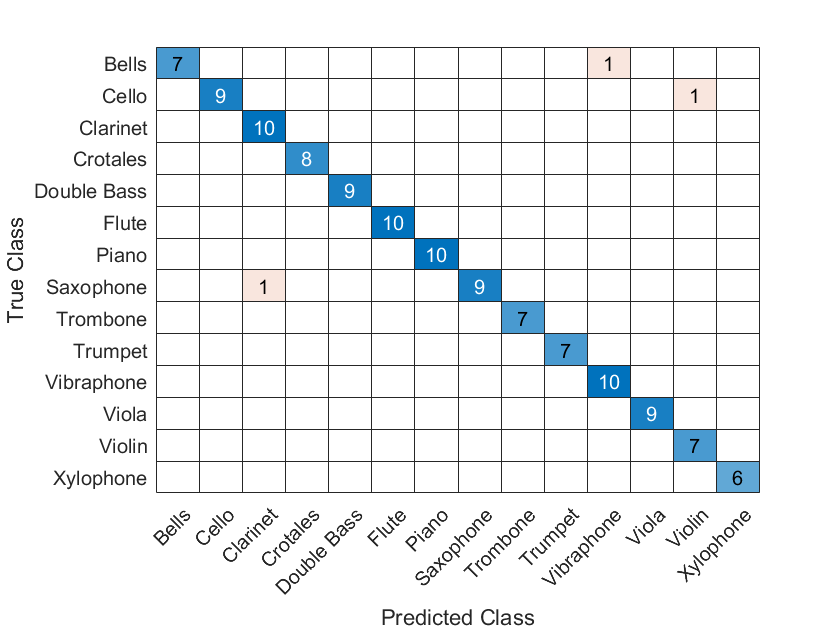

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [14×14 double]
         ClassLabels: [14×1 categorical]

  Show all properties


confusionchart(testds.Labels, testpred)